# **Theoretical power production**

define latitude of the solar pannels and declination of the sun

lat = 42 + 17/60

lat = 42.2833

dec = 23.45

dec = 23.4500

convert from degrees to radians

lat = (lat * pi) / 180

lat = 0.7380

dec = deg2rad(dec)

dec = 0.4093

Determine the amount of solar irradiance on the solar panels: $S_{panel}=S_{inc}\sin(\alpha)$, where $S_{inc} = 1.4883 \times 0.7^{\sin(\alpha)^{-0.678}}$ and $\alpha$ is the elevation of the sun given by $\sin(\alpha) = \sin(\delta)sin(\phi) + \cos(\delta)\cos(\phi)cos(15(LST-12))$

$\delta$ is declination and $\phi$ is latitude

t = 5.5:0.25:20

t =     5.5000    5.7500    6.0000    6.2500    6.5000    6.7500    7.0000    7.2500    7.5000    7.7500    8.0000    8.2500    8.5000    8.7500    9.0000    9.2500    9.5000    9.7500   10.0000   10.2500   10.5000   10.7500   11.0000   11.2500   11.5000   11.7500   12.0000   12.2500   12.5000   12.7500   13.0000   13.2500   13.5000   13.7500   14.0000   14.2500   14.5000   14.7500   15.0000   15.2500   15.5000   15.7500   16.0000   16.2500   16.5000   16.7500   17.0000   17.2500   17.5000   17.7500


LTS = t - 1 + 14.6/60

LTS =     4.7433    4.9933    5.2433    5.4933    5.7433    5.9933    6.2433    6.4933    6.7433    6.9933    7.2433    7.4933    7.7433    7.9933    8.2433    8.4933    8.7433    8.9933    9.2433    9.4933    9.7433    9.9933   10.2433   10.4933   10.7433   10.9933   11.2433   11.4933   11.7433   11.9933   12.2433   12.4933   12.7433   12.9933   13.2433   13.4933   13.7433   13.9933   14.2433   14.4933   14.7433   14.9933   15.2433   15.4933   15.7433   15.9933   16.2433   16.4933   16.7433   16.9933



sumangle = sin(dec)*sin(lat) + cos(dec)*cos(lat)*cosd(15*(LTS-12))

sumangle =     0.0484    0.0909    0.1342    0.1780    0.2222    0.2666    0.3109    0.3552    0.3990    0.4423    0.4848    0.5264    0.5669    0.6061    0.6438    0.6800    0.7144    0.7468    0.7772    0.8055    0.8314    0.8549    0.8759    0.8943    0.9101    0.9230    0.9332    0.9405    0.9449    0.9465    0.9451    0.9408    0.9337    0.9236    0.9108    0.8952    0.8770    0.8561    0.8327    0.8069    0.7788    0.7485    0.7161    0.6819    0.6458    0.6081    0.5690    0.5286    0.4870    0.4445


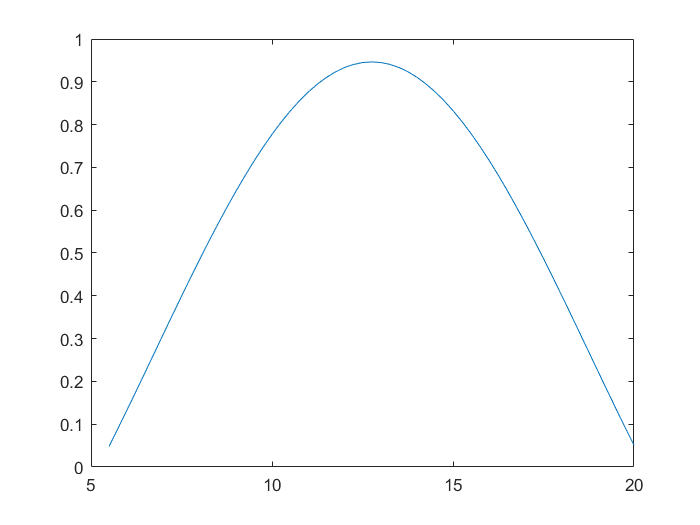

plot(t,sumangle)

S_inc = 1.4883 * 0.7.^(sumangle.^-0.678);

Calculate the final theoretical production for the entire solar panel array

production_theory = 270*S_inc.*sumangle

production_theory =     1.2109    5.9649   13.3975   22.6549   33.2037   44.6887   56.8525   69.4954   82.4536   95.5875  108.7741  121.9027  134.8724  147.5900  159.9693  171.9297  183.3963  194.2994  204.5742  214.1612  223.0055  231.0574  238.2719  244.6095  250.0353  254.5201  258.0396  260.5748  262.1122  262.6435  262.1659  260.6820  258.1998  254.7324  250.2985  244.9221  238.6324  231.4637  223.4554  214.6521  205.1034  194.8638  183.9926  172.5543  160.6184  148.2595  135.5578  122.5993  109.4766   96.2905


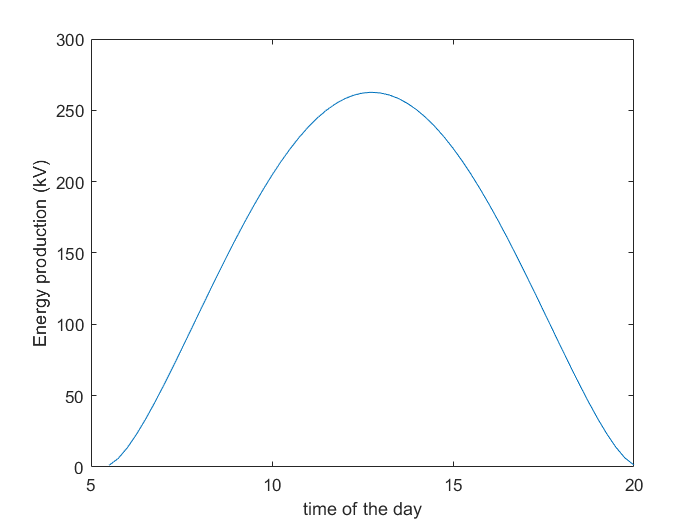

plot(t, production_theory)

xlabel("time of the day")
ylabel("Energy production (kV)")